## Arbitrary circuit analysis

This example goes through creating a **circuit** object from a **netlist**, which is contained in a text file. We start by calling the Circuit class and giving it the path to the netlist. The netlist automatically gets stored as a property called '**list**' on the circuit object. 

The circuit structure in this case, has been arbitrarily chosen.

circuit = Circuit('circuits/rlc_arbitrary.txt');
circuit.list

ans =     'Vcc 3 0 DC 1
     Vs 4 1 AC 1
     R2 3 2 1000
     R1 1 0 1000
     C1 4 0 0.000001
     C2 2 4 0.00001
     '


To symbolically **analyze** the circuit object, we give it to the **ELAB** class. This performs **MNV** to define the equations, which describe the circuit.

ELAB.analyze(circuit)

Symbolic analysis successful (0.529023 sec).


An **e**lectrical **c**ircuit is just a subclass of a generic system, which can be represented in any number of ways. For example, as a transfer function in the **s**ymbolic **d**omain. To see this representation, we can use the '**ec2sd**'-function.

sym_TF = ELAB.ec2sd(circuit, 3, 2)

Symbolic transfer function calculated successfully (5.623000e-03 sec).


$$sym\_TF = \frac{v_{2}}{v_{3}}=\frac{\mathrm{Vcc}+C_{1}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{\mathrm{Vcc}\,\left(C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1\right)}$$

Say the netlist contained numerical values for some, or all of its components. The evaluate function will use whatever equations were found by ELAB.analyze() to numerically **evaluate** the circuit. This numerical evaluation can now be used to create a Matlab-transfer-function object.

ELAB.evaluate(circuit)


Numerical evaluation successful (0.146422 sec).


num_TF = ELAB.ec2tf(circuit, 3, 2)

Transfer function object created successfully (2.498760e-02 sec).

num_TF =
 
     2100 s + 100000
  ---------------------
  s^2 + 2100 s + 100000
 
Continuous-time transfer function.



Matlab already has extensive functionality to handle transfer function objects.

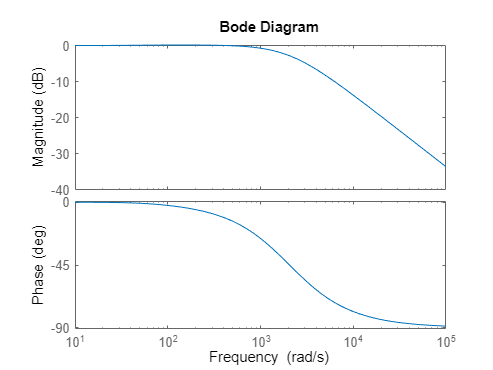

bode(num_TF);

During analysis, all node voltages and element currents were symbolically defined and stored in the circuit object.

circuit.symbolic_node_voltages

$$ans = \begin{array}{l} \left(\begin{array}{c} v_{1}=-\frac{R_{1}\,s\,\left(C_{1}\,\mathrm{Vs}-C_{2}\,\mathrm{Vcc}+C_{2}\,\mathrm{Vs}+C_{1}\,C_{2}\,R_{2}\,\mathrm{Vs}\,s\right)}{\sigma_{1}}\\ v_{2}=\frac{\mathrm{Vcc}+C_{1}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{\sigma_{1}}\\ v_{3}=\mathrm{Vcc}\\ v_{4}=\frac{\mathrm{Vs}+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1 \end{array}$$

circuit.symbolic_element_currents

$$ans = \begin{array}{l} \left(\begin{array}{c} i_{\mathrm{R2}}=\frac{C_{2}\,s\,\left(\mathrm{Vcc}-\mathrm{Vs}+C_{1}\,R_{1}\,\mathrm{Vcc}\,s\right)}{\sigma_{1}}\\ i_{\mathrm{R1}}=-\frac{s\,\left(C_{1}\,\mathrm{Vs}-C_{2}\,\mathrm{Vcc}+C_{2}\,\mathrm{Vs}+C_{1}\,C_{2}\,R_{2}\,\mathrm{Vs}\,s\right)}{\sigma_{1}}\\ i_{\mathrm{C1}}=\frac{\mathrm{Vs}+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{C_{1}\,\sigma_{1}}\\ i_{\mathrm{C2}}=\frac{\mathrm{Vcc}-\mathrm{Vs}+C_{1}\,R_{1}\,\mathrm{Vcc}\,s}{C_{2}\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1 \end{array}$$

And during evaluation, they were all numerically evaluated and stored. Since no numerical value was given for $V_{\textrm{cc}}$, the evaluation is partial.

circuit.numerical_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=-\frac{1000\,s\,\left(\frac{s}{100000000}+\frac{1}{1000000}\right)}{\frac{s^{2}}{100000}+\frac{21\,s}{1000}+1}\\ v_{2}=\frac{\frac{21\,s}{1000}+1}{\frac{s^{2}}{100000}+\frac{21\,s}{1000}+1}\\ v_{3}=1\\ v_{4}=\frac{\frac{s}{50}+1}{\frac{s^{2}}{100000}+\frac{21\,s}{1000}+1} \end{array}\right)$$